clear all;

1) Tutaj wpisuje się odpowiednio zera i bieguny:

z = [-3];
p = [-1 -2];
G0=zpk(z,p,1)

G0 =
 
     (s+3)
  -----------
  (s+1) (s+2)
 
Continuous-time zero/pole/gain model.



2) Tutaj podaje się różne współczynniki wzmocnienia:

k=[1,2,5,10,20];

3) Program oblicza poszczególne wartości:

n=length(k);
Gm=zeros(1,n);
Pm=zeros(1,n);
Wcg=zeros(1,n);
Wcp=zeros(1,n);
nachylenie=zeros(1,n);
argG0wW0=zeros(1,n);
fazaMargin=zeros(1,n);
fazaTwBodego=zeros(1,n);
h=0.01;

for i=1:n
   [Gm(i),Pm(i),Wcg(i),Wcp(i)] = margin(G0*k(i));
    nachylenie(i)=(G(z,p,k(i),Wcp(i)+h)-G(z,p,k(i),Wcp(i)-h))*Wcp(i)*log(10)/(2*h);
    argG0wW0(i)=pi/2*nachylenie(i);
    
    fazaMargin(i)=Pm(i);
    fazaTwBodego(i)=(pi()+argG0wW0(i))*180/pi();
end

4) Rysowanie wykresów:

    a) Wykresy zapasu fazy w funkcji pulsacji odcięcia

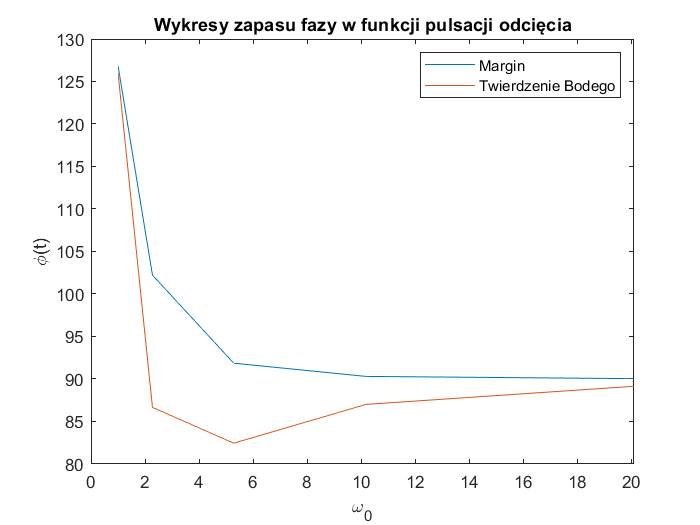

plot(Wcp,fazaMargin);
hold on;
plot(Wcp,fazaTwBodego);
hold off;
legend("Margin","Twierdzenie Bodego")
ylabel("\phi(t)");
xlabel("\omega_0");
title("Wykresy zapasu fazy w funkcji pulsacji odcięcia");

    b) Wykres Bodego odpowiadający pulsacji w0, dla której uzyskuje się największy błąd

[WartoscNajwiekszegoBleduWzoru,Index]=max(abs(fazaTwBodego-fazaMargin))

WartoscNajwiekszegoBleduWzoru = 15.5559

Index = 2

OdpowiadajacaMuPulsacja=Wcp(Index)

OdpowiadajacaMuPulsacja = 2.2755

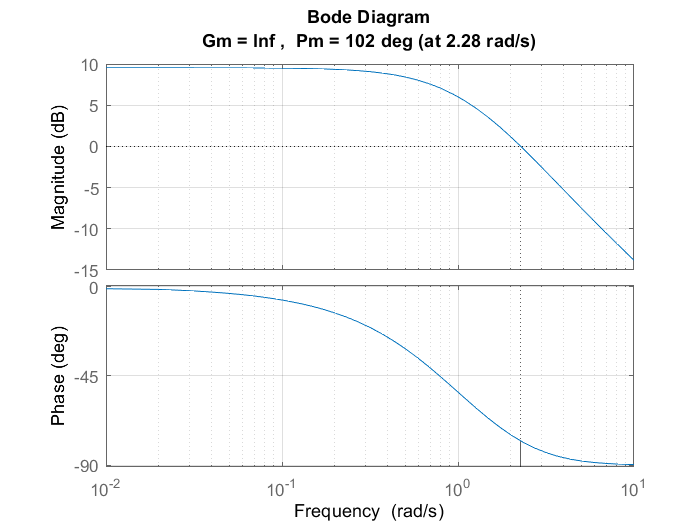

margin(G0*k(Index));
grid on;